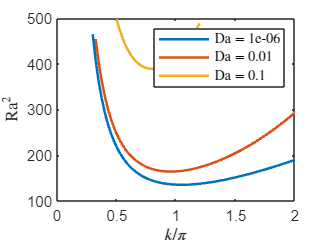

clear all
close all
clc
DaDa1=10.^[-6 -2 -1];

for ind=1:3
    Da=DaDa1(ind);
    if Da==10^(-6)
        load sigma_Da=-6.mat
    end
    if Da==10^(-2)
        load sigma_Da=-2.mat
    end
    if Da==10^(-1)
        load sigma_Da=-1.mat
    end
    if Da==10^(0)
        load sigma_Da=1.mat
    end

    l=1;
    l2=1;
    for j=1:length(kk)
        flag=0;
        n=1;
        while n<=length(RR)-1 && flag==0
            if (real(sigma(n,j))<0 && real(sigma(n+1,j))>0 && abs(imag(sigma(n+1,j)))<10^(-6)) || (real(sigma(n,j))>0 && real(sigma(n+1,j))<0 && abs(imag(sigma(n+1,j)))<10^(-6))
                if flag==0
                    realRa(l)=RR(n);
                    realwavenumber(l)=kk(j);
                    l=l+1;
                    flag=1;
                end
            end
            n=n+1;
        end
    end
    plot(realwavenumber,realRa.^2,'LineWidth',1.5)
    xlabel('$k/\pi$',Interpreter='latex')
ylabel('$\mathrm{Ra}^2$',Interpreter='latex')
    hold on
    LegendStrings= "$\mathrm{Da}=$" + string(DaDa1);
legend(LegendStrings,Interpreter="latex",Location="northeast")

    % [Rc,index]=min(realRa.^2);
    % wavec=realwavenumber(index);
    realRa=[];
    realwavenumber=[];

end